% The steps of the project

% 1. Face Detection: Use face detection algorithms to find the face within the image.
% 2. Feature Detection: Apply feature detection algorithms to locate the eyes and mouth.
% 3. Geometric Transformation: Apply transformations to rotate, scale, and translate the image so that the eyes (and if possible, the mouth) are aligned to a standard template.
% 4. Cropping and Resizing: Crop the aligned face to a standard size and resize it if necessary.
% 5. PCA and Eigenface Generation: Once the images are normalized and aligned, proceed with PCA and eigenface generation as you've already done.
% 6. Recognition: When a new image is received, apply the same preprocessing steps to it before projecting it onto the eigenface space for recognition.

addpath('functions');

% Main-file
% img1 = imread("images/DB1/db1_01.jpg");
% img2 = imread("images/DB1/db1_02.jpg");
% img3 = imread("images/DB1/db1_03.jpg");

% PART 1 (purpose to find eyes)

% Load dataset

% Skin detection? (DB2)

% Illuminant compensation

% White balance

% Image color correction?

% Convert to YCbCR (combine with HSV?)

% Face mask

% Detect face

% % ginput, BOB lab 1. Level slicing

% Eye map: Chrominance & Luminance

% Mouth map?

% Eye mask + face mask (grade 5)

% Normilization

% PART 2, face matching
addpath('functions');

% Parameters
numImages = 16;  % Total number of images
commonSize = [400, 300];  % Common dimensions for all images

% Initialize the data matrix
dataMatrix = zeros(numImages, prod(commonSize));

% Folder path
folderPath = 'images/DB1';
imageFiles = dir(fullfile(folderPath, '*.jpg'));  % Adjust the extension if necessary

% Load, preprocess, and reshape images
for i = 1:numImages
    % Load image
    img = imread(fullfile(folderPath, imageFiles(i).name));
    % Convert to grayscale
    grayImg = im2gray(img);
    % Resize image
    resizedImg = imresize(grayImg, commonSize);
    % Reshape and add to data matrix
    dataMatrix(i, :) = reshape(resizedImg, 1, []);
end

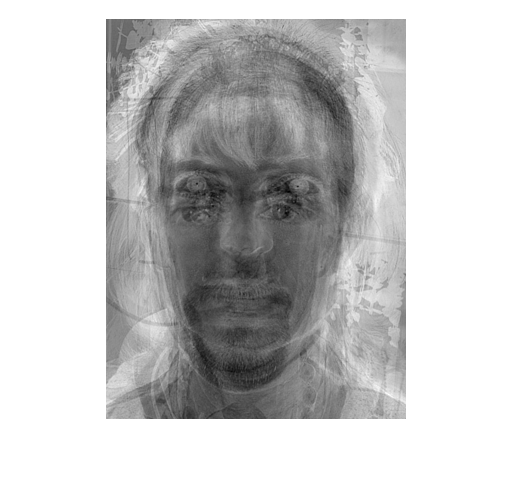

% Mean Centering
meanFace = mean(dataMatrix);
meanCenteredData = dataMatrix - meanFace;

% Apply PCA - computing eigenvectors of ATA
[coeff, score, ~] = pca(meanCenteredData);

% Select the number of principal components/eigenfaces to use
numEigenfaces = 10;  % For example, using the first 10 eigenfaces

% Eigenfaces
eigenfaces = coeff(:, 1:numEigenfaces);

% Display the first eigenface as an example
eigenface1 = reshape(eigenfaces(:,1), commonSize);
figure, imshow(eigenface1, []);


% Project each face in the training set onto the eigenface space
weights = score(:, 1:numEigenfaces);

% The above weights can now be used to represent and compare faces

% ----- Recognition Part -----
% For a new query image, you would preprocess it in the same way,
% project it onto the eigenface space, and then compare it with
% the weights of the training set to find the closest match.

% Assuming you have the following variables defined from before:
% eigenfaces - the matrix containing the eigenfaces
% meanFace - the mean face vector
% weights - the weights of the training images in the eigenface space
% commonSize - the [height, width] of the preprocessed images

% ----- Preprocess and Project a Query Image -----
% Load and preprocess the query image in the same way as the training images
queryImagePath = 'images/DB1/db1_01.jpg';  % Replace with the path to the query image
queryImg = imread(queryImagePath);
queryImgGray = im2gray(queryImg);
queryImgResized = imresize(queryImgGray, commonSize);
queryImgVector = reshape(queryImgResized, 1, []);

% Subtract the mean face
queryImgMeanSubtracted = double(queryImgVector) - meanFace;

% Project the query image onto the eigenface space to get its weights
queryWeights = queryImgMeanSubtracted * eigenfaces;

% ----- Recognize the Face -----
% Initialize the minimum distance and index
minDistance = inf;
minIndex = 0;

% Loop through the weights of the training set to find the closest match
for i = 1:numImages
    distance = norm(weights(i,:) - queryWeights);
    if distance < minDistance
        minDistance = distance;
        minIndex = i;
    end
end

% ----- Decision -----
% Define a threshold for recognition (this will need to be set based on your dataset)
threshold = 1000;  % This is an arbitrary value, adjust this based on your dataset

% Check if the closest match is below the threshold
if minDistance < threshold
    fprintf('The query image matches with image #%d in the training set.\n', minIndex);
else
    fprintf('No match found in the training set for the query image.\n');
end

The query image matches with image #1 in the training set.


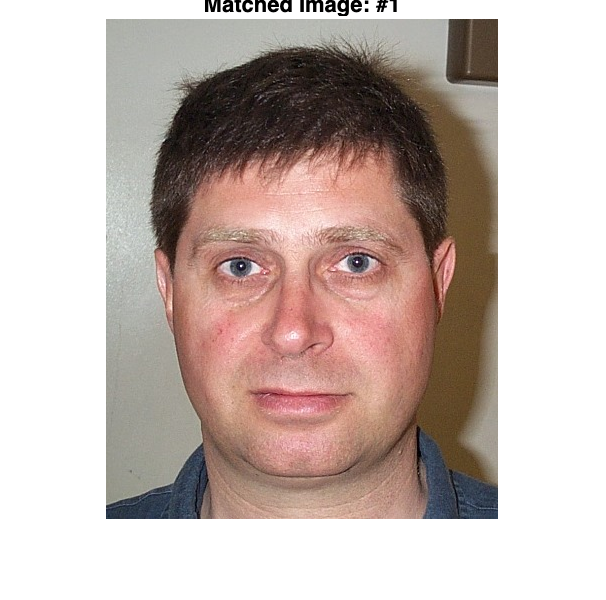


% Optionally, display the matched image
if minIndex > 0
    matchedImagePath = fullfile(folderPath, imageFiles(minIndex).name);
    matchedImg = imread(matchedImagePath);
    figure, imshow(matchedImg), title(sprintf('Matched Image: #%d', minIndex));
end